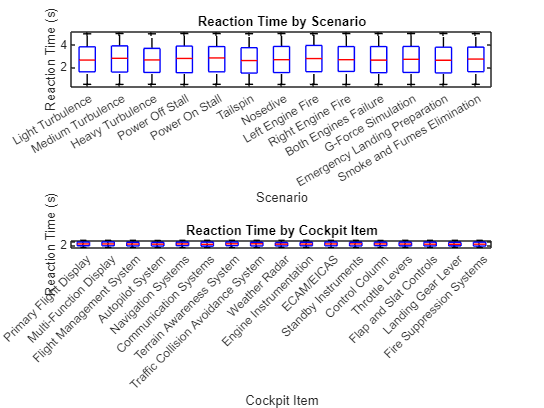

% MATLAB Script for Analyzing Pilot Performance Dataset

% Importing the dataset
data = readtable('Pilot_Performance_Dataset_Updated.csv');

% Extracting unique scenarios and cockpit items
scenarios = unique(data.Scenario);
cockpitItems = unique(data.Cockpit_Item);

% Reaction Time Analysis
figure;
subplot(2, 1, 1);
boxplot(data.Reaction_Time_s, data.Scenario);
title('Reaction Time by Scenario');
xlabel('Scenario');
ylabel('Reaction Time (s)');

subplot(2, 1, 2);
boxplot(data.Reaction_Time_s, data.Cockpit_Item);
title('Reaction Time by Cockpit Item');
xlabel('Cockpit Item');
ylabel('Reaction Time (s)');

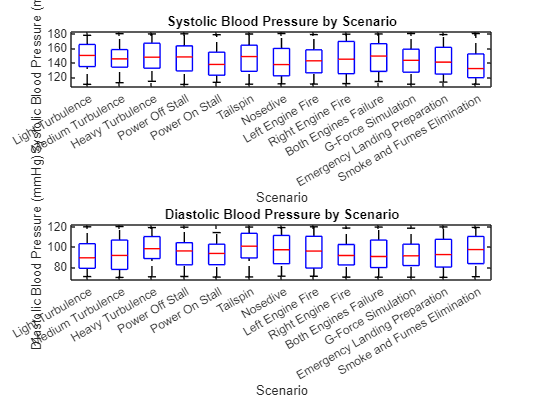


% Blood Pressure Analysis
figure;
subplot(2, 1, 1);
boxplot(data.Blood_Pressure_systolic, data.Scenario);
title('Systolic Blood Pressure by Scenario');
xlabel('Scenario');
ylabel('Systolic Blood Pressure (mmHg)');

subplot(2, 1, 2);
boxplot(data.Blood_Pressure_diastolic, data.Scenario);
title('Diastolic Blood Pressure by Scenario');
xlabel('Scenario');
ylabel('Diastolic Blood Pressure (mmHg)');

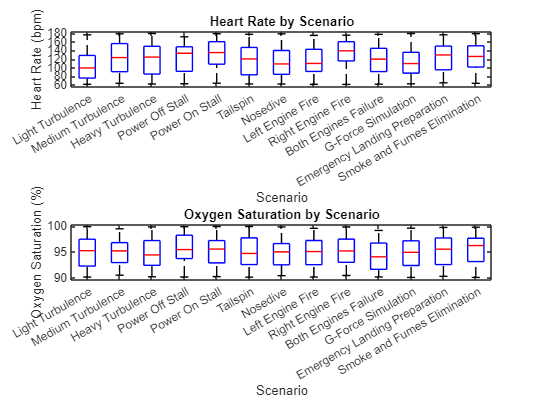


% Heart Rate and Oxygen Saturation Analysis
figure;
subplot(2, 1, 1);
boxplot(data.Heart_Rate, data.Scenario);
title('Heart Rate by Scenario');
xlabel('Scenario');
ylabel('Heart Rate (bpm)');

subplot(2, 1, 2);
boxplot(data.Oxygen_Saturation, data.Scenario);
title('Oxygen Saturation by Scenario');
xlabel('Scenario');
ylabel('Oxygen Saturation (%)');

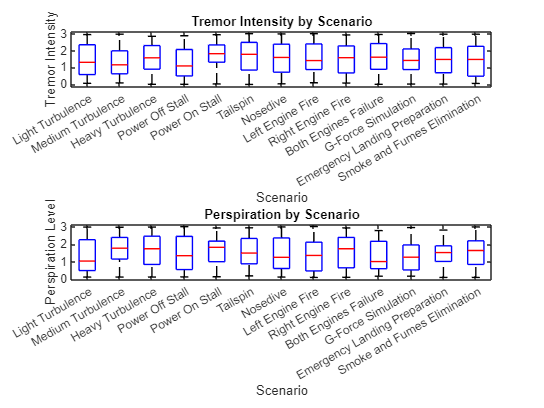


% Tremor Intensity and Perspiration Analysis
figure;
subplot(2, 1, 1);
boxplot(data.Tremor_Intensity, data.Scenario);
title('Tremor Intensity by Scenario');
xlabel('Scenario');
ylabel('Tremor Intensity');

subplot(2, 1, 2);
boxplot(data.Perspiration, data.Scenario);
title('Perspiration by Scenario');
xlabel('Scenario');
ylabel('Perspiration Level');


% Calculate average reaction time per pilot
avgReactionTime = varfun(@mean, data, 'InputVariables', 'Reaction_Time_s', 'GroupingVariables', 'Pilot_ID');

% Calculate accuracy percentage per pilot
correctActions = strcmp(data.Correct_Action, 'Yes');
accuracyTable = table(data.Pilot_ID, correctActions, 'VariableNames', {'PilotID', 'CorrectActions'});
accuracyPercentage = varfun(@mean, accuracyTable, 'InputVariables', 'CorrectActions', 'GroupingVariables', 'PilotID');

% Merge reaction time and accuracy into a single table
pilotPerformance = outerjoin(avgReactionTime, accuracyPercentage, 'Keys', 'PilotID', 'MergeKeys', true);

Error using tabular/outerjoin (line 33)
Unrecognized table variable name 'PilotID'.


% Add a combined performance score (lower is better, so invert reaction time)
pilotPerformance.CombinedScore = pilotPerformance.mean_Reaction_Time_s ./ pilotPerformance.mean_CorrectActions;

% Sort pilots by combined score
sortedPilots = sortrows(pilotPerformance, 'CombinedScore');

% Display the top 10 pilots
top10Pilots = sortedPilots(1:10, :);

% Plot top 10 pilots' performance
figure;
bar(categorical(string(top10Pilots.PilotID)), top10Pilots.CombinedScore);
title('Top 10 Pilots by Performance Score');
xlabel('Pilot ID');
ylabel('Performance Score (lower is better)');
grid on;

% Plot reaction time and accuracy of top 10 pilots
figure;
subplot(2, 1, 1);
bar(categorical(string(top10Pilots.PilotID)), top10Pilots.mean_Reaction_Time_s);
title('Top 10 Pilots by Average Reaction Time');
xlabel('Pilot ID');
ylabel('Average Reaction Time (s)');
grid on;

subplot(2, 1, 2);
bar(categorical(string(top10Pilots.PilotID)), top10Pilots.mean_CorrectActions * 100);
title('Top 10 Pilots by Accuracy Percentage');
xlabel('Pilot ID');
ylabel('Accuracy Percentage (%)');
grid on;

% Save the figures
saveas(figure(1), 'Reaction_Time_Analysis.png');
saveas(figure(2), 'Blood_Pressure_Analysis.png');
saveas(figure(3), 'Heart_Rate_and_Oxygen_Saturation.png');
saveas(figure(4), 'Tremor_and_Perspiration.png');
saveas(figure(5), 'Top_10_Pilots_Performance_Score.png');
saveas(figure(6), 'Top_10_Pilots_Reaction_Time_and_Accuracy.png');